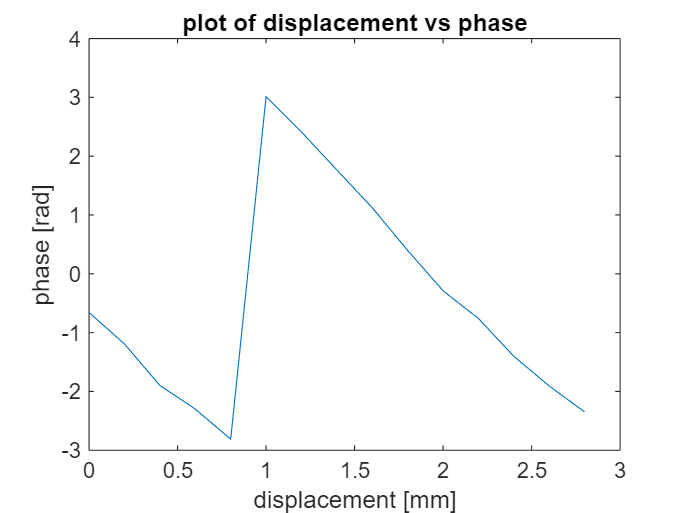

clc
clear all 
close all
t0 = load('Position0_01.mat');
%% Task2.1
yar = hilbert(t0.A);
dphi = zeros(1,15);
for i= 1:8
    ti = load(['Position0-000' num2str(i+1) '_01.mat']);
    yai = hilbert(ti.A);
    dphi(i) = angle(sum((yai.*conj(yar))./abs(yar).^2));
end
for i= 9:15
    ti = load(['Position0-00' num2str(i+1) '_01.mat']);
    yai = hilbert(ti.A);
    dphi(i) = angle(sum((yai.*conj(yar))./abs(yar).^2));
end
dplot=0:0.2:3-0.2;
figure(1)
plot(dplot,dphi)
xlabel('displacement [mm]')
ylabel('phase [rad]')
title('plot of displacement vs phase')

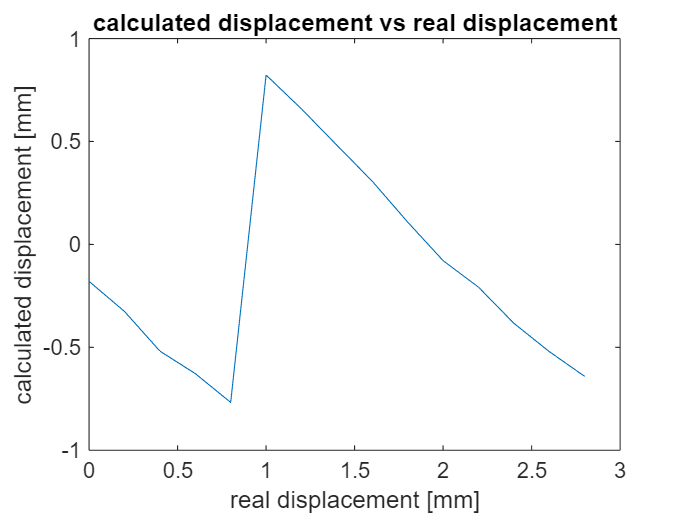


%% Task2.2
fc = 100e3; %Hz
Cp = 343000; %mm/s
lambda = Cp/fc;

d=dphi*lambda/(4*pi);
dun=unwrap(dphi)*lambda/(4*pi);

figure(2)
plot(dplot,d)
ylabel('calculated displacement [mm]')
xlabel('real displacement [mm]')
title('calculated displacement vs real displacement')

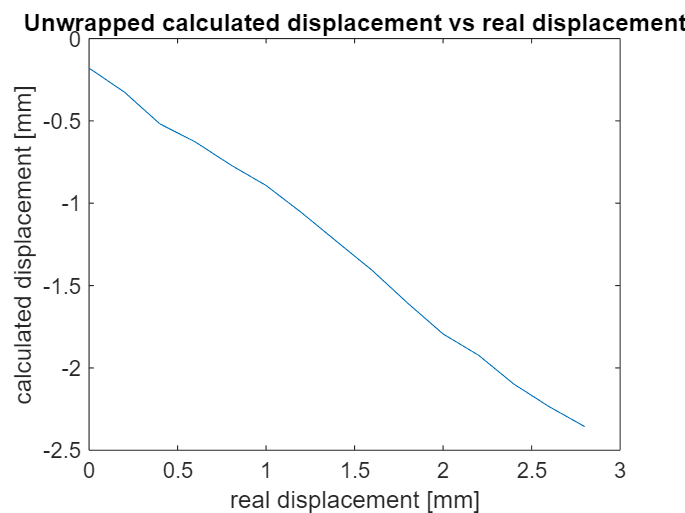

figure(3)
plot(dplot,dun)
ylabel('calculated displacement [mm]')
xlabel('real displacement [mm]')
title('Unwrapped calculated displacement vs real displacement')

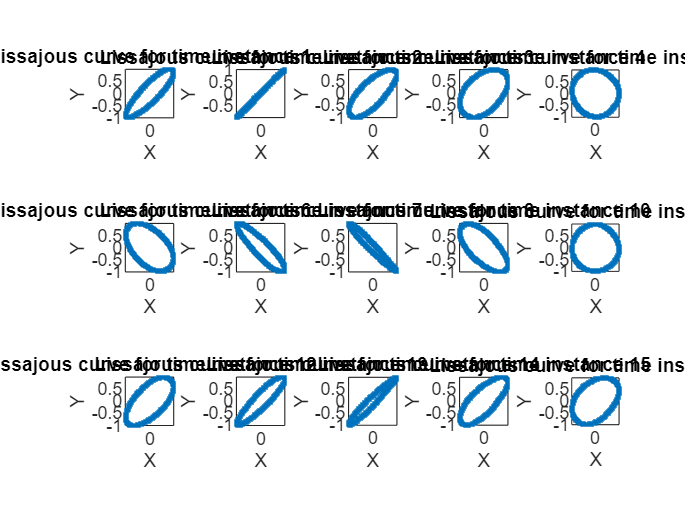


%% Task2.3
figure(4)
Y_max = zeros(1, 15);  % Initialize Y_max array to store max values of B
Y_max_i = zeros(1, 15);
B = t0.B ./ max(abs(t0.B));
Y0 = zeros(1,15);
for i= 1:8
    ti = load(['Position0-000' num2str(i+1) '_01.mat']);
    % Normalize A and B signals
    A = ti.A ./ max(abs(ti.A));
    % Plotting Lissajous curve
    subplot(3, 5, i)
    plot(B, A, '.')
    axis equal tight
    xlabel('X')
    ylabel('Y')
    title(['Lissajous curve for time instance ', num2str(i)])
    
    % Store the maximum value of B
    [~,index] = min(abs(B));
    Y0(i) = A(index);
    [Y_max(i),Y_max_i(i)] = max(A);
    %checking for relative position of max(Y) relative to Y0
    if B(Y_max_i(i))>=0
        phi00(i) = asin(Y0(i) / Y_max(i));
        %disp('t')
    else
        %disp('f')
        phi00(i) =pi- asin(Y0(i) / Y_max(i));
    end
    %disp(['phi',num2str(i+1),': ', num2str(phi00(i))])
end
for i= 9:15
    ti = load(['Position0-00' num2str(i+1) '_01.mat']);
    % Normalize A and B signals
    A = ti.A ./ max(abs(ti.A));
    % Plotting Lissajous curve
    subplot(3, 5, i)
    plot(B, A, '.')
    axis equal tight
    xlabel('X')
    ylabel('Y')
    title(['Lissajous curve for time instance ', num2str(i+1)])
    
    % Store the maximum value of B
    [~,index] = min(abs(B));
    Y0(i) = A(index);
    [Y_max(i),Y_max_i(i)] = max(A);
    %checking for relative position of max(Y) relative to Y0
    if B(Y_max_i(i))>0
        phi00(i) = asin(Y0(i) / Y_max(i));
        %disp('t')
    else
        %disp('f')
        phi00(i) =pi- asin(Y0(i) / Y_max(i));
    end
    %disp(['phi',num2str(i+1),': ', num2str(phi00(i))])
end

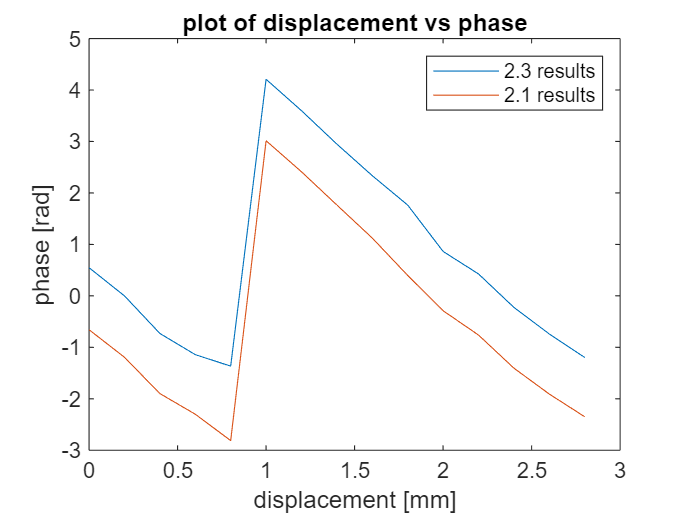


figure(5)
plot(dplot,phi00), hold on
plot(dplot,dphi), hold off
ylabel('phase [rad]')
xlabel('displacement [mm]')
title('plot of displacement vs phase')
legend('2.3 results','2.1 results')

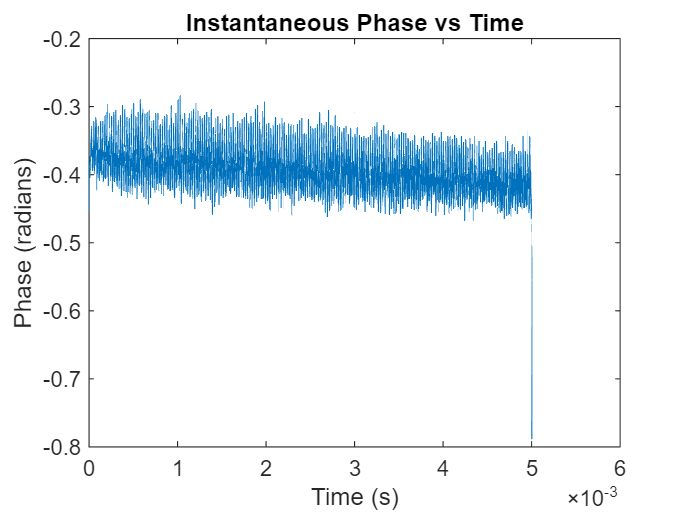

%%
clc
clear all 
close all
%% Task3.1
load('speed7mms.mat')
A_hil = hilbert(A);
B_hil = hilbert(B);
num=A_hil.*conj(B_hil);
den = abs(B_hil).^2;
phi = angle(num./den);

% Calculate the wavelength (λ)
Cp = 343000; % Speed of sound in air at 27 degrees Celsius in mm/s
fc = 100e3; % Frequency of the wave in Hz
lambda = Cp / fc; %in mm
% Transform the phase shift to distance
delta_phi = unwrap(phi);
distance = (delta_phi*lambda / (4 * pi));
% Estimate the speed of the plate movement
time = (0:length(distance)-1) * Tinterval;
% Fit a linear function to the distance-time data
P = polyfit(time, distance, 1);
speed_estimated = P(1);
% Plot the instantaneous phase
figure(1);
plot(time, phi);
title('Instantaneous Phase vs Time');
xlabel('Time (s)');
ylabel('Phase (radians)');

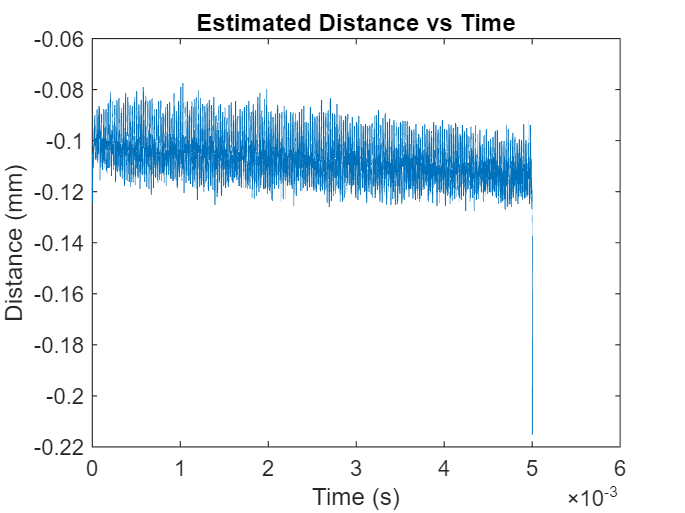

% Plot the distance estimation
figure(2);
plot(time, distance);
title('Estimated Distance vs Time');
xlabel('Time (s)');
ylabel('Distance (mm)');

% Display the estimated speed
disp(['Estimated Speed: ', num2str(speed_estimated), ' m/s']);

Estimated Speed: -2.4192 m/s


disp(['Nominal Speed: 7 mm/s']);

Nominal Speed: 7 mm/s



%% Task3.2


files = {'speed5mms.mat', 'speed7mms.mat', 'speed9mms.mat', 'speed11mms.mat', 'speed13mms.mat', 'speed15mms.mat'};
nominal_speeds = [5, 7, 9, 11, 13, 15];
estimated_speeds = zeros(1, length(files));
errors = zeros(1, length(files));

for i = 1:length(files)

    % Load the data
    load(files{i});
    % Compute the analytical signals using the Hilbert transform
    A_hil = hilbert(A);
    B_hil = hilbert(B);
    % Calculate the numerator and denominator for the instantaneous phase
    num = A_hil .* conj(B_hil);
    den = abs(B_hil).^2;
    % Calculate the instantaneous phase
    phi = angle(num ./ den);
    % Calculate the wavelength (λ)
    Cp = 343000; % Speed of sound in air in mm/s
    fc = 100e3; % Frequency of the wave in Hz
    lambda = Cp / fc; % Wavelength in mm
    % Transform the phase shift to distance
    delta_phi = unwrap(phi);
    distance = (delta_phi / (2 * pi)) * (lambda / 2);
    % Estimate the speed of the plate movement
    
    time = (0:length(distance)-1) * Tinterval; 
    % Fit a linear function to the distance-time data
    P = polyfit(time, distance, 1);
    estimated_speeds(i) = P(1);
    % Calculate the error
    errors(i) = abs(estimated_speeds(i) - nominal_speeds(i));
end

% Display the results
results_table = table(files', nominal_speeds', estimated_speeds', errors', ...
                      'VariableNames', {'File', 'NominalSpeed_mm_per_s', 'EstimatedSpeed_mm_per_s', 'Error_mm_per_s'});
disp(results_table);

           File           NominalSpeed_mm_per_s    EstimatedSpeed_mm_per_s    Error_mm_per_s
    __________________    _____________________    _______________________    ______________

    {'speed5mms.mat' }              5                      -1.9908                6.9908    
    {'speed7mms.mat' }              7                      -2.4192                9.4192    
    {'speed9mms.mat' }              9                      -3.2701                 12.27    
    {'speed11mms.mat'}             11                     -0.10968                 11.11    
    {'speed13mms.mat'}             13                      -5.7909                18.791    
    {'speed15mms.mat'}             15                      -6.8017                21.802    

